С нулем

A = [90 -30 210]./180.*pi;

Норм

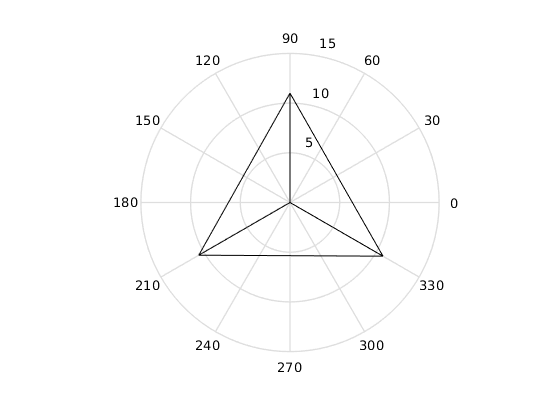

U = [11 10.8 10.6];
PolPlot(A,U,0)

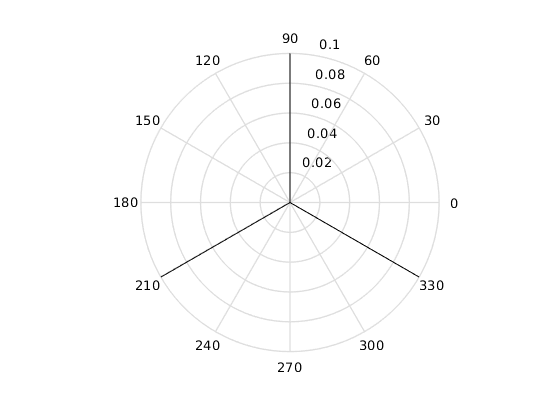


I = [0.1 0.1 0.1];
PolPlotForI(A,I,0)

Аварийный

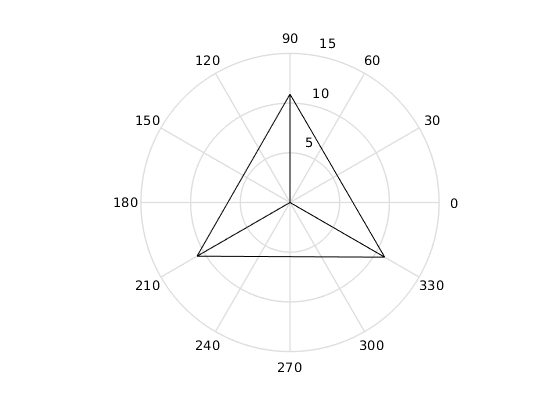

U = [10.9 11 10.8];
PolPlot(A,U,0)

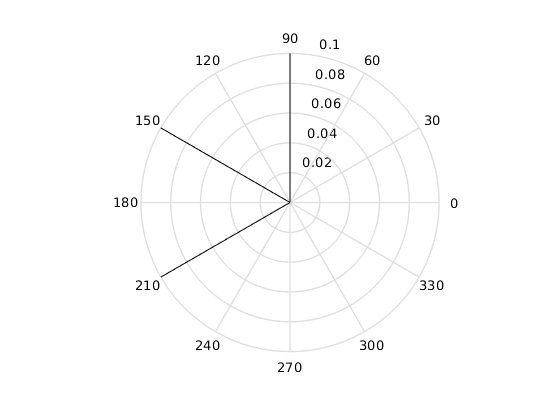


I = [0.1 -0.1 0.1];
PolPlotForI(A,I,0)

Несиметричный

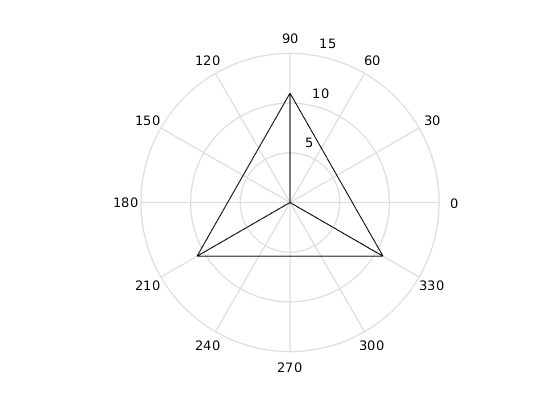

U = [11 10.8 10.8];
PolPlot(A,U,0)

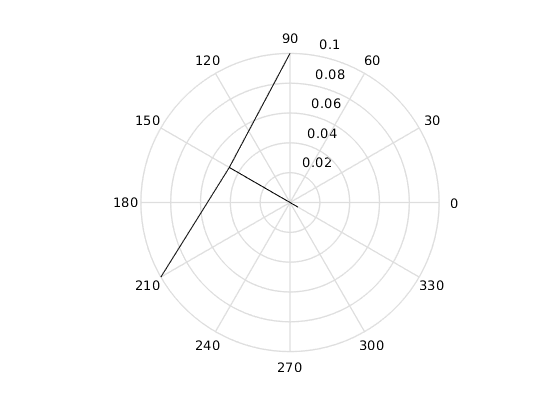


I = [0.1 0.053 0.1];
PolPlotForI(A,I,0.047)

Без нуля

A = [90 -30 210]./180.*pi;

Норм

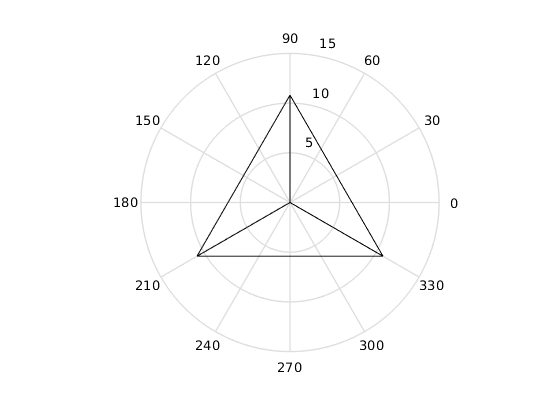

U = [10.8 10.8 10.8];
PolPlot(A,U,0)


I = [0.1 0.1 0.1];
PolPlotForI(A,I,0)

Аварийный

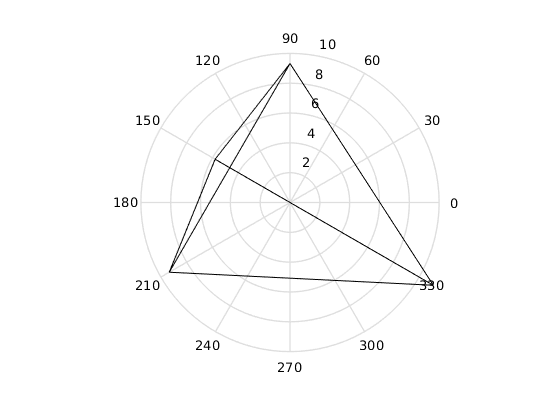

U = [9.32 16.9 9.35];
PolPlot(A,U,5.8)

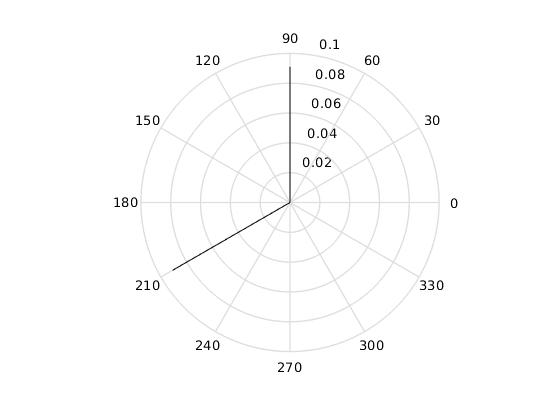


I = [0.091 0 0.091];
PolPlotForI(A,I,0)

Несиметричный

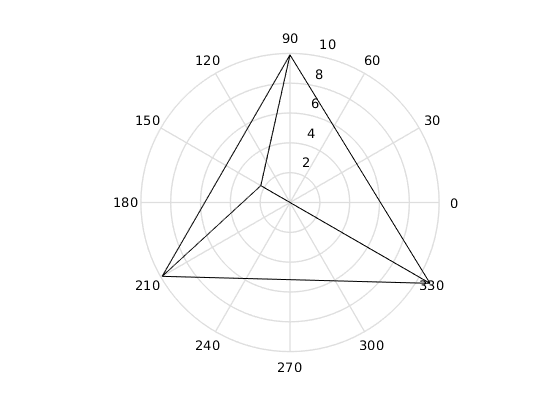

U = [9.9 13.1 9.9];
PolPlot(A,U,2.26)

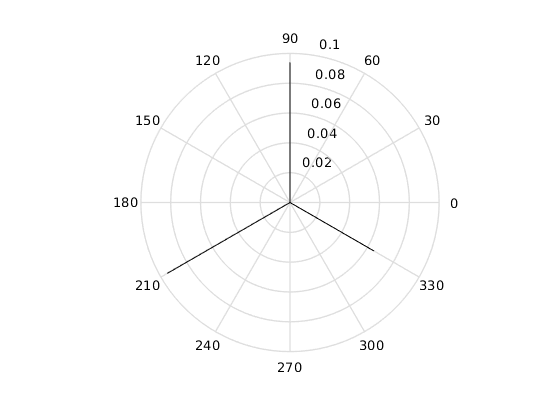


I = [0.094 0.065 0.095];
PolPlotForI(A,I,0)

Функции для обрыва и короткого замыкания  в цепи Б

function PolPlot(A,U,N)

polar([A(2)+pi A(1)],[N U(1)], '-k')
hold on
polar([A(2)+pi A(2)],[N U(2)-N], '-k')
polar([A(2)+pi A(3)],[N U(3)], '-k')
polar([0 A(2)+pi],[0 N], '-k')
polar([A(1) A(2)],[U(1) U(2)-N], '-k')
polar([A(2) A(3)],[U(2)-N U(3)], '-k')
polar([A(3) A(1)],[U(3) U(1)], '-k')
ylim('manual')
grid minor
hold off

end
function PolPlotForI(A,U,N)

polar([A(2)+pi A(1)],[N U(1)], '-k')
hold on
polar([A(2)+pi A(2)],[N U(2)-N], '-k')
polar([A(2)+pi A(3)],[N U(3)], '-k')
polar([0 A(2)+pi],[0 N], '-k')
ylim('manual')
grid minor
hold off

end